# 원하는 폴더에서 첫 번째 사진 가져오기

% 현재 디렉토리의 정보를 가져옵니다.
d = dir;
% 폴더만 필터링합니다.
isub = [d(:).isdir];
% '.'과 '..'을 제외한 폴더 이름만 가져옵니다.
folderNames = {d(isub).name}';
folderNames(ismember(folderNames,{'.','..'})) = [];

% 현재 폴더의 경로를 저장합니다.
currentFolder = pwd;


cd(folderNames{26}); % 지정한 폴더로 이동하기

## Get all imges

    exosome=dir("*.tif");
    [s,~]=size(exosome);


% %%단일이미지 분석할 때
% I0 = im2gray(imread(exosome(1).name));
% [i1, i2] = size(I0);
% mip_full = zeros(i1, i2, 'double');
% imshow(0.5*mat2gray(I0))

## Check the turn on point

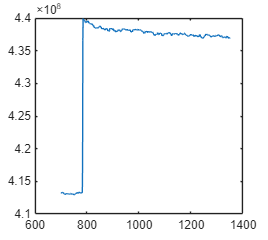

    tic
    chs=700;
    window=chs:1350;
    [~,w]=size(window);
    IntS=zeros([1,w]);
    for i=window(1):window(end)
        IntS(i-window(1)+1)=sum(sum(im2gray(imread(exosome(i).name))));
    end
    plot(window,IntS)

    toc

경과 시간은 7.460403초입니다.


    L_ind=find(IntS==max(IntS))

L_ind = 86

## Check the first image

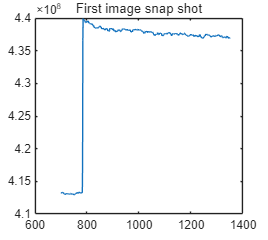

    LO=chs+L_ind;
    I=im2gray(imread(exosome(LO).name));
    [i1, i2]=size(I);
    title("First image snap shot")

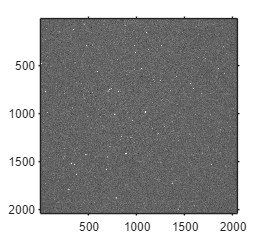

    imshow(10*mat2gray(I))
    axis on

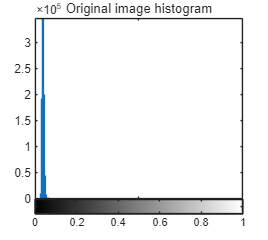

    imhist(mat2gray(I))
    title("Original image histogram")

%% ------------------ Global Normalization + ROI Crop ------------------

% 중심 좌표 (직접 지정)
x_center = 1270;   % 원하는 x좌표 (가로)
y_center = 1110;  % 원하는 y좌표 (세로)

% ROI 크기 설정 (픽셀 단위)
roi_size = [550, 550];  % [height, width] 형태


% 1️⃣ 전역 정규화 (global normalization)
I_norm = mat2gray(I);  % 전체 이미지를 0~1 범위로 고정

% imshow(I_norm);
% title('Globally Normalized I image');
% axis on;

% 2️⃣ ROI 영역 계산
roi_rect = round([
    x_center - roi_size(2)/2, ...  % x 시작점
    y_center - roi_size(1)/2, ...  % y 시작점
    roi_size(2), ...               % 너비
    roi_size(1)                    % 높이
]);

% 3️⃣ ROI 자르기 (정규화된 이미지 기준으로)
cropped_ROI = imcrop(I_norm, roi_rect);

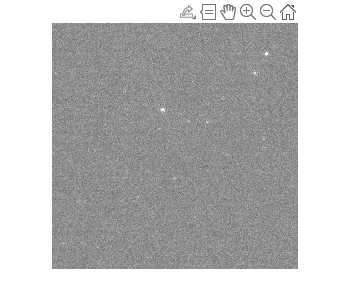

% 4️⃣ Crop 결과 표시 - 너무 작은 거 표시할 때
imshow(5*cropped_ROI, 'InitialMagnification', 10000, 'Interpolation','nearest'); % 10000%로 표시

% axis image off


exportgraphics(gcf, 'cropped_ROI_ev_sr1_re_11x11_time4.png', 'Resolution', 300);

## 원하는 FFT stack 불러오기

exosome_frequency_stack = exosomeData.('n3_5_cd9_7_sr20_exosome_frequency_stack');

## FFT image generation n=?

Sr=20;
exosome_improve_Im=zeros([i1, i2]);2

ans = 2


tic
n=round(40/Sr);
for i=1:i1
    for j=1:i2
        exosome_improve_Im(i,j)=sqrt(sumsqr(exosome_frequency_stack(i,j,2:n+1)));
    end
end
toc

경과 시간은 8.774329초입니다.


## Original first snap shot vs FFT image

montage({5*(mat2gray(I)),30*(uint8(255*mat2gray(exosome_improve_Im)))});

## FFT images (10X intensities)

% scaling_up=7.2;5
% scaling_up=8.5;
mm=max(max(exosome_improve_Im))

mm = 219.0284

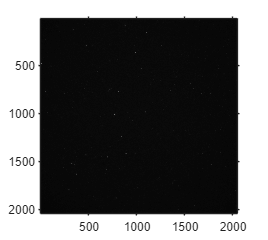

if mm>255
    scaling_up=1;
    I_n=mat2gray(exosome_improve_Im);
    imshow(I_n)
    II=(scaling_up*uint8(double(255*I_n)));
    imshow(2*II)
    axis on
else
    scaling_up=255;
    II=uint8(scaling_up*mat2gray((exosome_improve_Im)));
    imshow(2*II)
    axis on
end

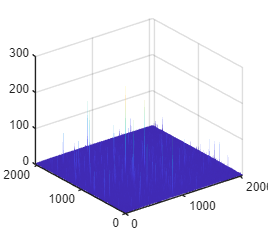

surf(II)
shading interp


%% ------------------ Global Normalization + ROI Crop ------------------

% 중심 좌표 (직접 지정)
% fft_x_center = 906;   % 원하는 x좌표 (가로)
% fft_y_center = 1227;  % 원하는 y좌표 (세로)

% ROI 크기 설정 (픽셀 단위)
% roi_size = [10, 10];  % [height, width] 형태


% 1️⃣ 전역 정규화 (global normalization)
fft_norm = mat2gray(II);  % 전체 이미지를 0~1 범위로 고정

% imshow(fft_norm);
% title('Globally Normalized fft image');
% axis on;

% 2️⃣ ROI 영역 계산
roi_rect = round([
    x_center - roi_size(2)/2, ...  % x 시작점
    y_center - roi_size(1)/2, ...  % y 시작점
    roi_size(2), ...               % 너비
    roi_size(1)                    % 높이
]);

% 3️⃣ ROI 자르기 (정규화된 이미지 기준으로)
cropped_ROI_FFT = imcrop(fft_norm, roi_rect);

% 4️⃣ Crop 결과 표시 (추가 normalization 없음)
% figure;
% imshow(1*cropped_ROI_FFT);  % mat2gray 다시 안 씀!

% axis on

imshow(5*cropped_ROI_FFT, 'InitialMagnification', 10000, 'Interpolation','nearest'); % 10000%로 표시
% axis image off

exportgraphics(gcf, 'cropped_ROI_bead_fft_11x11.png', 'Resolution', 300);

%% =================== 20Hz 정규화 컷오프 & E/RSS ===================
% 여기서는 exosome_frequency_stack을 그대로 stack으로 사용
stack  = exosome_frequency_stack;              % [i1 x i2 x Nfreq]
Nfreq  = size(stack, 3);                       % = L/2 + 1
L      = 2*(Nfreq - 1);                        % FFT 길이 복원
Fs     = round(40 / Sr);                       % 01번에서 썼던 것과 동일 가정 (ORIG_FPS=40)

% f-axis (0 ~ Nyquist)
f = Fs * (0:(L/2)) / L;                        % 길이 Nfreq
f_end  = f(end);                               % = Fs/2

% 20Hz 정규화 1.03 기준 컷오프
%  - 20 * (f / f_end) = f(Hz) (Sr=1, Fs=40 → f_end=20)
%  - f_norm <= 1.03 → 약 1.03 Hz까지 low 구간
f_norm  = 20 * (f / f_end);
idx_cut = find(f_norm <= 1.03, 1, 'last');
if isempty(idx_cut) || idx_cut < 2
    idx_cut = 2;                               % DC(1) 제외, 최소 2부터
end

lo_bins = 2:idx_cut;
hi_bins = (idx_cut+1):Nfreq;
if isempty(hi_bins)
    hi_bins = Nfreq+1:Nfreq;                   % hi가 비지 않도록 형식상 처리
end


% 전체 이미지에서 low / high 구간 에너지 및 RSS
E_lo_all   = squeeze(sum( double(stack(:,:,lo_bins)).^2, 3 ));
RSS_lo_all = sqrt(E_lo_all);
E_hi_all   = squeeze(sum( double(stack(:,:,hi_bins)).^2, 3 ));
RSS_hi_all = sqrt(E_hi_all);

% 표시용 이미지 (0~255 스케일)
% II_lo = uint8(255 * mat2gray(RSS_lo_all));
% II_hi = uint8(255 * mat2gray(RSS_hi_all));


% figure; 
% tiledlayout(1,2,'Padding','compact','TileSpacing','compact');
% nexttile; imshow(10*II_lo); title('RSS (low bins)');
% nexttile; imshow(5*II_hi); title('RSS (high bins)');


%% =================== first_pixel_fft / time ===================
% ROI 중심 좌표를 픽셀 좌표로 보정
px = max(1, min(i2, round(x_center)));   % 열(x)
py = max(1, min(i1, round(y_center)));   % 행(y)

% 1) 주파수 도메인: 해당 픽셀의 FFT 스펙트럼
first_pixel_fft = double(squeeze(stack(py, px, :))).';   % [1 x Nfreq]

% 2) 시간 도메인: 원본 tif를 다시 읽어서 같은 픽셀의 time trace 구성
ds_idx = 1:Sr:s;                             % Sr 스텝으로 샘플링된 프레임 인덱스
if numel(ds_idx) < L
    error('ds_idx 길이(%d)가 L(%d)보다 작습니다.', numel(ds_idx), L);
end
ds_idx = ds_idx(1:L);                        % L에 맞게 자르기

first_pixel_time = zeros(1, L, 'double');
for tt = 1:L
    idx = min(max(1, ds_idx(tt)), s);
    fimg = im2gray(imread(exosome(idx).name));
    % 이 버전에서는 median 필터를 쓰지 않았다고 가정
    first_pixel_time(tt) = double(fimg(py, px));
end

% 3) 저주파 / 고주파 에너지 및 RSS, 에너지 비 (dB)
E_lo_px   = sum(first_pixel_fft(lo_bins).^2);
E_hi_px   = sum(first_pixel_fft(hi_bins).^2);
RSS_lo_px = sqrt(E_lo_px + eps);
RSS_hi_px = sqrt(E_hi_px + eps);
energy_ratio_dB = 10*log10( (E_lo_px + eps) / (E_hi_px + eps) );

fprintf('\n=== 20Hz-정규화 컷오프 요약 (이전 03번 버전용) ===\n');
fprintf('Fs=%.3f Hz, L=%d → Nyquist=%.6f Hz\n', Fs, L, f(end));
fprintf('norm20=1.03 ↔ f_cut=%.6f Hz @ bin=%d (DC=1)\n', f(idx_cut), idx_cut);
fprintf('bins low = 2..%d, bins high = %d..%d\n', idx_cut, max(idx_cut+1,2), Nfreq);
fprintf('Pixel(x=%d,y=%d): E_low=%.6f, E_high=%.6f, RSS_low=%.6f, RSS_high=%.6f, ER(dB)=%.3f\n', ...
        px, py, E_lo_px, E_hi_px, RSS_lo_px, RSS_hi_px, energy_ratio_dB);

%% =================== first_pixel_time / first_pixel_fft Plot ===================
% 시간축 (Fs, L을 이용)
t = (0:L-1) / Fs;    % [초] 단위 시간 벡터 (L개 샘플)

figure('Name','Time vs Frequency (first pixel)','Position',[100 100 600 500]);
tiledlayout(2,1,'Padding','compact','TileSpacing','compact');

% 1) Time domain plot
nexttile;
plot(t, first_pixel_time, '-');
xlabel('Time (s)');
ylabel('Intensity (a.u.)');
title(sprintf('Time trace at pixel (%d,%d)', px, py));
grid on;

% 2) Frequency domain plot (single-sided spectrum amplitude)
nexttile;
stem(f, first_pixel_fft, 'r', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('|X(f)| (a.u.)');
title('Single-sided FFT amplitude (same pixel)');
% xlim([0 f(end)]);

grid on;

%% =================== N에 따른 상위 성분 복원 + Frechet Distance ===================
% 여기서는 방금 계산한 first_pixel_time 을 원본 신호로 사용
original_signal = first_pixel_time;   % [1 x L] 시간 신호
fft_result      = fft(original_signal);   % 원본 FFT (복소수)

% (참고용) 진폭/위상 분리
fft_amplitude = abs(fft_result / L);  % 진폭
fft_phase     = angle(fft_result);    % 위상

% 테스트할 N 값들
N_values = [1, 5, 10, 20, 40, 80];

% Frechet distance 저장용
frechet_distances = zeros(size(N_values));

% 원본과 복원된 신호 비교 (한 figure 안에 중첩)
figure;
hold on;

% 원본 신호 (파란색)
plot(1:L, original_signal, 'b', 'LineWidth', 2, 'DisplayName', 'Original Signal');

% 복원 신호들의 투명도
alpha_value = 0.12;

% 상위 N개 성분만 사용하여 복원 + Frechet 계산
for idx = 1:length(N_values)
    N = N_values(idx);

    % 상위 N개의 주파수 성분 선택 (진폭 기준)
    mags         = abs(fft_result);
    mags_sorted  = sort(mags, 'descend');
    threshold    = mags_sorted(N);
    reduced_fft  = fft_result .* (mags >= threshold);   % 상위 N개만 남김

    % 역 FFT로 복원
    reconstructed_signal = real(ifft(reduced_fft));

    % Frechet Distance 계산
    frechet_distances(idx) = frechet_distance(original_signal, reconstructed_signal);

    % 복원된 신호 플로팅 (빨간색, 투명도)
    plot(1:L, reconstructed_signal, 'Color', [1, 0, 0, alpha_value], 'LineWidth', 1.5);
end

ylim([0 1500]);   % 필요하면 범위 조정

ax = gca;
ax.Box    = 'off';
ax.XColor = 'none';
ax.YColor = 'none';
grid on;
legend('off');
hold off;

%% N별 복원 신호를 개별 변수(N_1, N_5, N_10, ...)로 저장
for idx = 1:length(N_values)
    N = N_values(idx);

    % 상위 N개의 주파수 성분 선택
    mags        = abs(fft_result);
    mags_sorted = sort(mags, 'descend');
    threshold   = mags_sorted(N);
    reduced_fft = fft_result .* (mags >= threshold);

    % 역 FFT로 복원
    reconstructed_signal = real(ifft(reduced_fft));

    % 변수 이름 동적으로 생성해서 base workspace에 저장
    var_name = sprintf('N_%d', N);
    assignin('base', var_name, reconstructed_signal);

    fprintf('✅ Saved reconstructed signal as variable: %s\n', var_name);
end

%% === Original vs Cutoff-iFFT Overlay (append after existing code) ===

% 20 Hz 정규화 컷오프에서의 실제 주파수 (이미 위에서 f, idx_cut 계산됨)
f_cut = f(idx_cut);          % [Hz]

% 원본 신호 FFT
X  = fft(original_signal);
L  = numel(original_signal);

% 주파수축 생성 (센터 정렬)
X_shift   = fftshift(X);
freq_full = (-L/2:L/2-1) * (Fs / L);   % [-Fs/2, Fs/2) 구간

% |f| <= f_cut 만 남기는 low-pass mask
mask         = abs(freq_full) <= f_cut;
X_lp_shift   = X_shift .* mask;
X_lp         = ifftshift(X_lp_shift);

% 컷오프까지의 성분만으로 역 FFT
recon_cutoff = real(ifft(X_lp));

% 원본 vs 컷오프-iFFT 오버레이 플롯
figure;
plot(t, original_signal, 'b', 'LineWidth', 2); hold on;
plot(t, recon_cutoff,   'r', 'LineWidth', 1.8);
xlabel('Time (s)');
ylabel('Intensity (a.u.)');
title(sprintf('Original vs Cutoff-iFFT (|f| \\leq %.2f Hz)', f_cut));
legend({'Original','Cutoff-iFFT'}, 'Location','best');
grid on;



% Frechet Distance 값 출력
disp('Frechet Distances:');
disp(frechet_distances);

% Frechet Distance vs N (원 값)
figure;
plot(N_values, frechet_distances, '-ob', 'LineWidth', 1.5, 'MarkerSize', 8);
xlabel('Number of FFT Components (N)');
ylabel('Frechet Distance');
ylim([0 1500]);   % 필요시 조정
title('Frechet Distance vs Number of FFT Components');
grid on;


% 정규화된 Frechet Distance (0~1)
normalized_frechet_distance = mat2gray(frechet_distances);

figure;
plot(N_values, normalized_frechet_distance, '-ob', 'LineWidth', 1.5, 'MarkerSize', 8);
xlabel('Number of FFT Components (N)');
ylabel('Normalized Frechet Distance');
title('Normalized Frechet Distance vs N');
grid on;

% Workspace 에도 저장 (표 형태)
N_components = N_values(:);
normalized_frechet_distance_table = table( ...
    N_components, normalized_frechet_distance(:), ...
    'VariableNames', {'FFT_Components_N', 'Normalized_Frechet_Distance'} );

assignin('base', 'normalized_frechet_distance',        normalized_frechet_distance);
assignin('base', 'normalized_frechet_distance_table',  normalized_frechet_distance_table);

disp('✅ Saved "normalized_frechet_distance" and "normalized_frechet_distance_table" to Workspace.');


%% ===== 통일 규칙: 전역 mat2gray → 동일 ROI crop (LO / FFT / MIP) =====
% (I, exosome_improve_Im, roi_rect, ds_idx, exosome, i1, i2, s 사용)

% 1) LO (첫 프레임 I) 전역 정규화 후 ROI crop
LO_norm_full = mat2gray(I);                 % [i1 x i2]
LO_crop      = imcrop(LO_norm_full, roi_rect);

% 2) FFT 이미지(exosome_improve_Im) 전역 정규화 후 ROI crop
FFT_norm_full = mat2gray(exosome_improve_Im);
FFT_crop      = imcrop(FFT_norm_full, roi_rect);

% 3) MIP (ds_idx 타임라인에 대해 최대투영) 생성 후 전역 정규화 + ROI crop
mip_full = zeros(i1, i2, 'double');
for tt = 1:numel(ds_idx)
    idx = min(max(1, ds_idx(tt)), s);           % 안전 범위 클램프
    It  = im2gray(imread(exosome(idx).name));
    mip_full = max(mip_full, double(It));       % 타임라인 내 최대값
end
MIP_norm_full = mat2gray(mip_full);
MIP_crop      = imcrop(MIP_norm_full, roi_rect);


% ===== 세 이미지 동일 ROI 비교용 빠른 프리뷰 =====
figure('Name','Unified panels (global mat2gray → crop)','Position',[100 100 900 300]);
tiledlayout(1,3,'Padding','compact','TileSpacing','compact');

nexttile; imshow(8*LO_crop, 'InitialMagnification', 10000, 'Interpolation','nearest');
title('LO (first frame)');

nexttile; imshow(8*FFT_crop, 'InitialMagnification', 10000, 'Interpolation','nearest');
title('FFT');

nexttile; imshow(8*MIP_crop, 'InitialMagnification', 10000, 'Interpolation','nearest');
title('MIP');


## Gaussian blurring

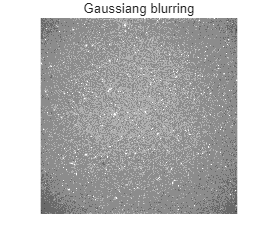

%%원래 II에는 exosome_improve_Im이 저장되어 있음 / 분석하고 싶은 걸로 II 바꿔주기

% II=MIP_norm_full;  
% II=LO_norm_full; %mat2gray 적용x인 원본 LO는 'I'에 저장되어 있음
% II=FFT_norm_full;  %mat2gray 적용x인 원본 fft는 'exosome_improve_Im'에 저장되어 있음
% II=I0; %아얘 단일 이미지 분석할 때
% II=I

II_ad=imgaussfilt(1*II,0.5);
imshow(35*II_ad)
title("Gaussiang blurring")


% mm=II_ad %아얘 단일 이미지 분석할 때

## Mono otsu's threshold

if mm>250
    level=1.2*graythresh(uint8(II_ad))
    imhist(uint8(II_ad))
    xline(level,'r',"LineWidth",2)

## Multi threshold

level = 0.0824

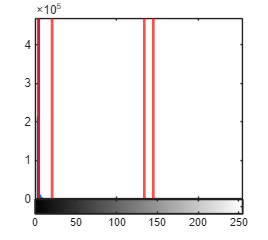

    if level>=0.3 & level<0.3005

        thresh_num=3;
        thresh = multithresh(II_ad,thresh_num);
        level=double(thresh(2))/255

        imhist(uint8(II_ad))
        xline(thresh,'r',"LineWidth",2)
        title("FFT image histogram")

    elseif level>=0.3005 & level<0.6

        thresh_num=4;
        thresh = multithresh(II_ad,thresh_num);
        level=double(thresh(2))/255

        imhist((II_ad))
        xline(thresh,'r',"LineWidth",2)
        title("FFT image histogram")


     elseif level>=0.6

        thresh_num=5;
        thresh = multithresh(II_ad,thresh_num);
        level=double(thresh(2))/255

        imhist((II_ad))
        xline(thresh,'r',"LineWidth",2)
        title("FFT image histogram")

    end

else
    thresh_num=4;
    thresh = multithresh(II_ad,thresh_num);
    level=double(thresh(2))/255
    imhist((II_ad))
    xline(thresh,'r',"LineWidth",2)
end

## Single Threshold

% T = adaptthresh(II_ad, level);
T = adaptthresh(II_ad, 0.1, "NeighborhoodSize", [1023 1025])

T =     0.0170    0.0170    0.0170    0.0171    0.0171    0.0171    0.0171    0.0172    0.0172    0.0172    0.0172    0.0172    0.0173    0.0173    0.0173    0.0173    0.0173    0.0174    0.0174    0.0174    0.0174    0.0174    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176    0.0177    0.0177    0.0177    0.0177    0.0177    0.0178    0.0178    0.0178    0.0178    0.0178    0.0179    0.0179    0.0179    0.0179    0.0180    0.0180    0.0180    0.0180
    0.0170    0.0170    0.0171    0.0171    0.0171    0.0171    0.0171    0.0172    0.0172    0.0172    0.0172    0.0172    0.0173    0.0173    0.0173    0.0173    0.0173    0.0174    0.0174    0.0174    0.0174    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176    0.0176    0.0177    0.0177    0.0177    0.0177    0.0178    0.0178    0.0178    0.0178    0.0178    0.0178    0.0179    0.0179    0.0179    0.0179    0.0180    0.0180    0.0180    0

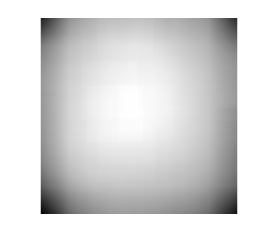

%% default : "NeighborhoodSize",[4089 4097] / 2045 2049 / 3067 3073 / 1023 1025 / 585 585
BW = imbinarize(II_ad,T);

imshow(mat2gray(T))

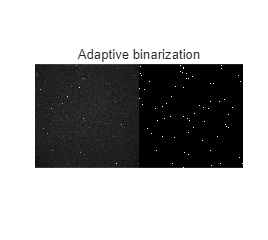


imshowpair(10*II_ad, BW, 'montage')
title("Adaptive binarization")

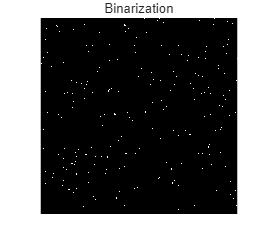


imshow(BW)
title("Binarization")

## Opening image - final processing

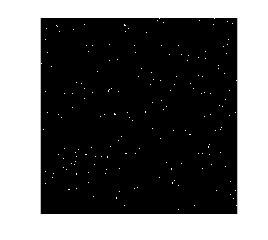

se1 = strel('disk',1);
J_1 = imopen(BW,se1);
imshow(J_1)

% title("Opening final image")

## Final image information

% J_1=J_1(36:2044,:);
R=regionprops(J_1,"all");

size_thres=25

size_thres = 23

RA=R([R.Area]>5 & [R.Area] <= size_thres);
RAC=sum([RA.Circularity] > 0.95);


% cd(currentFolder); % 원래 폴더로 돌아가기

%% ============================================================
%% (파일 맨 끝에 함수 정의 두기) Frechet Distance 함수
function d = frechet_distance(P, Q)
    % Frechet Distance 계산 함수 (1D 신호 P, Q)
    n = length(P);
    m = length(Q);
    C = inf(n, m);
    C(1, 1) = norm(P(1) - Q(1));

    for i = 2:n
        C(i, 1) = max(C(i-1, 1), norm(P(i) - Q(1)));
    end

    for j = 2:m
        C(1, j) = max(C(1, j-1), norm(P(1) - Q(j)));
    end

    for i = 2:n
        for j = 2:m
            C(i, j) = max( ...
                min([C(i-1, j), C(i, j-1), C(i-1, j-1)]), ...
                norm(P(i) - Q(j)) ...
            );
        end
    end
    d = C(n, m);
end